# Template of Manipulator Short project: Skull tumor surgery

**List of to do:**

The Robotic environment must contain:

1.-  **Taula d'operacions: **L'entorn de treball está compost per una** taula principal** de dimensions 1.2 x 1.6 m on es col·loca al pacient  i una **taula auxiliar** de 50cmx50cm on hi estarà el Puma. Per defecte la taula principal esta inclinada 30º y la taula auxiliar sempre esta connectada a l'extrem superior.

Dimensions inicials de les taules

clc;
clear;
close all;
mainTableW = 1.2; % amplada de la taula pricipal
mainTableH = 1.6; % llargada de la taula pricipal
auxTableW = 0.5; % amplada de la taula auxiliar
auxTableH = 0.5; % llargada de la taula auxiliar

Parametres de posició inicial. En aquest cas, considerarem que 

mainTablePositionX = 0;
mainTablePositionY = 0;
mainTablePositionZ = 0; % elevació de la taula principal
mainTableTilingDegrees = 0;
mainTableTilingZOffset = mainTableH * tan(deg2rad(mainTableTilingDegrees));
mainTablePosition = [mainTablePositionX mainTablePositionY+mainTableH/2 mainTablePositionZ];

auxTableTilingDegrees = 0;
auxTableTilingZOffset = auxTableH * tan(deg2rad(auxTableTilingDegrees));
auxTableYOffset = (mainTableH/2)-auxTableH/2;
auxTableXOffset = (mainTableW/2)+auxTableW/2;
auxTablePosition = [auxTableXOffset auxTableYOffset mainTableTilingZOffset] + mainTablePosition;

mainTablePoints = getTablePointsMatrixFromCentre(mainTablePosition, mainTableW, mainTableH, mainTableTilingZOffset)

mainTablePoints =    -0.6000    0.6000    0.6000   -0.6000
         0         0    1.6000    1.6000
         0         0         0         0


auxTablePoints = getTablePointsMatrixFromCentre(auxTablePosition, auxTableW, auxTableH, auxTableTilingZOffset)

auxTablePoints =     0.6000    1.1000    1.1000    0.6000
    1.1000    1.1000    1.6000    1.6000
         0         0         0         0


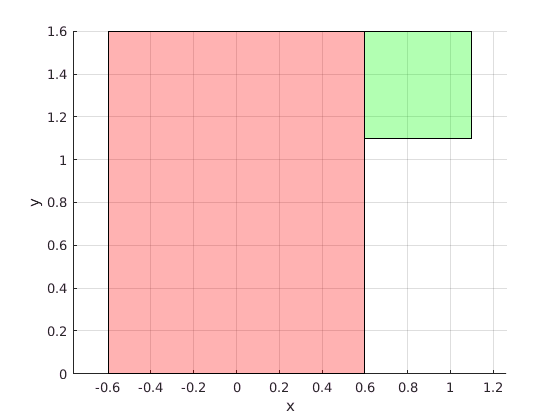

mainTableFigureId = 30;
auxTableFigureId = 40;
figure(1);
hold on
drawTable(mainTablePoints, 'r');
drawTable(auxTablePoints, 'g');
axis equal
grid
xlabel('x')
ylabel('y')
zlabel('z')

2.- A 3D model of a human body on the operating table. Use the Workspace given, or other you might find.

*Add your comemnts here..... be concise*

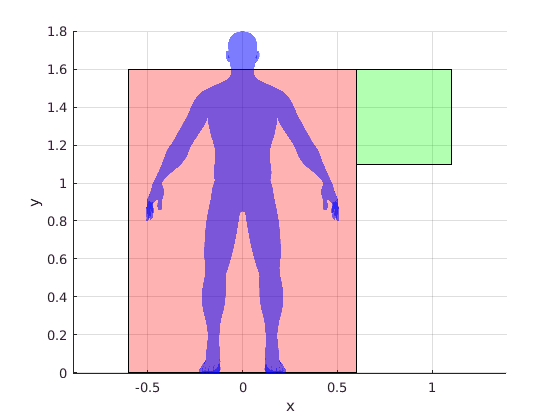

[V,F] = readOBJ('Human_body.obj','Quads',true);
 % Turn triangles into degenerate quads 
humanbodyh = max(V(:,2));
V = V./humanbodyh;
V = V.*1.8;
humanbodyh = max(V(:,2)) - min(V(:,2));
humanbodyw = max(V(:,1)) - min(V(:,1));
humanbodyd = max(V(:,3)) - min(V(:,3));
V(:,3) = V(:,3) + humanbodyd/2;
patch('Faces',F,'Vertices',V,'FaceColor','blue', 'FaceAlpha',.3, 'EdgeColor', 'none');

3.- A human skull model, embedded in the head of the human. Place the fiducials.

*Add your comemnts here.....be concise*

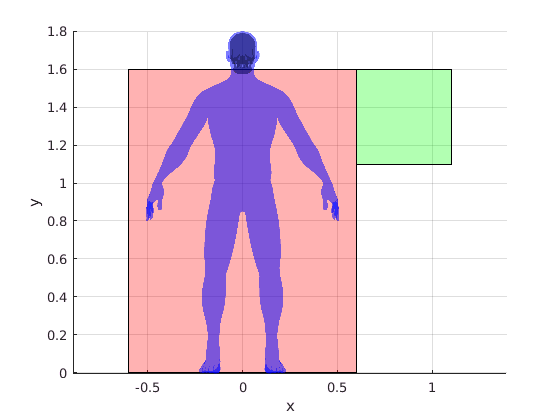

[VS,FS] = readOBJ('Skull.obj');
% make the sull smaller
skullh = max(VS(:,3)) - min(VS(:,3));
VS = VS./skullh;
VS = [VS(:,1).*0.19 VS(:,2).*0.165 VS(:,3).*0.215];
totalVerticesS = size(VS,1);
onesMat = ones(totalVerticesS, 1);
NV = [VS onesMat]';
% skulld = max(VS(:,2)) - min(VS(:,2));
% Rotation and translation
NV = trotx(-90,'deg') * transl(0,-0.155,1.575) * NV;
VS = NV(1:3,:)';
patch('Faces',FS,'Vertices',VS,'FaceColor','black', 'FaceAlpha',.3, 'EdgeColor', 'none');

4.- Use the Dicom images to get the points of the outer perimeter of the tumor relative to some reference frame located in the human skull.

*Add your comemnts here.....be concise*

*Punts del tumor*

VT = xlsread('Puntos Tumor.xlsx','Relativos','A2:C103');

*First approach:**  Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

5.- Display all necessary Reference Frames

*Add your comemnts here.....be concise*

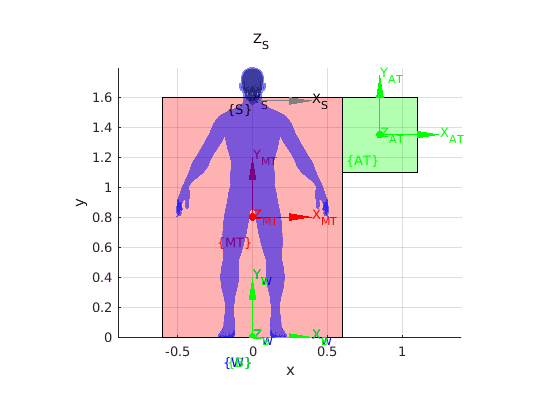

W = eye(4);
trplot(W, 'frame','W','text_opts',{'FontSize', 10},'arrow','color', 'b','thick',1,...
          'width', 1,'length',0.4 )
MT = transl(mainTablePosition)*W;
trplot(MT, 'frame','MT','text_opts',{'FontSize', 10},'arrow','color', 'r','thick',1,...
          'width', 1,'length',0.4 )
AT = transl(auxTablePosition)*W;
trplot(AT, 'frame','AT','text_opts',{'FontSize', 10},'arrow','color', 'g','thick',1,...
          'width', 1,'length',0.4 )
B = transl([0 0 humanbodyd/2]) * W;
trplot(B, 'frame','B','text_opts',{'FontSize', 10},'arrow','color', 'g','thick',1,...
          'width', 1,'length',0.4 )
S = trotx(-90,'deg') * transl(0,-0.155,1.575) * W;
trplot(S, 'frame','S','text_opts',{'FontSize', 10},'arrow','color', 'black','thick',1,...
          'width', 1,'length',0.4 )

6.- Place the 6R Robot manipulator nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

*// TODO Corregir error de Puma -> Index Exceeds the number of arrayElements si no se ejecutan en figures separados*

7.- Get the transformation that maps tumor points in Robot Frame.

*Add your comemnts here.....be concise*

%% put your code Here

8.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

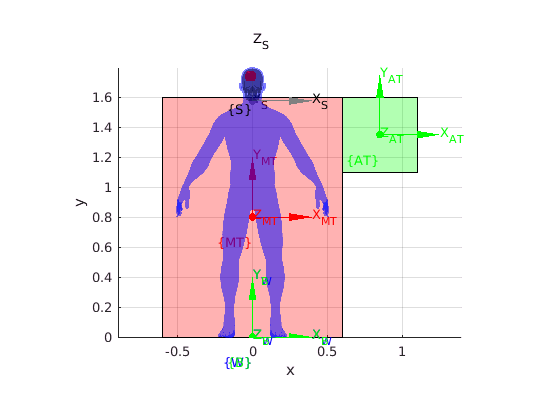

totalVerticesT = size(VT,1);
onesMat = ones(totalVerticesT, 1);
NVT = [VT onesMat]';
% Rotation and translation
skullh = max(VS(:,2));
skullw = min(VS(:,1));
skulld = min(VS(:,3));
tumorh = max(VT(:,3)) - min(VT(:,3));
tumorw = max(VT(:,1)) - min(VT(:,1));
tumord = max(VT(:,2)) - min(VT(:,2));
NVT = trotx(-90,'deg') * transl(skullw+0.06,-skulld-0.120,skullh-tumorh-23*0.0014) * NVT;
VT = NVT(1:3,:)';
tumorh = max(VT(:,3)) - min(VT(:,3));
tumorw = max(VT(:,1)) - min(VT(:,1));
tumord = max(VT(:,2)) - min(VT(:,2));
s = scatter3(VT(:,1),VT(:,2),VT(:,3), 20,'filled', 'MarkerFaceColor','red');

9.- Prepare a script that perform a biopsy. Zoom in the scene

*Creem a l'espai del robot prototipus dels epsiloides contenidors del tumor i del crani *

%% put your code Here

mdl_puma560
figure(8)
robotY = mainTableH/2 + skullh/2 + 0.5;
robotPosition = mainTablePosition + [0 robotY 0];
p560.base = transl(robotPosition);
p560.plot(qz, 'workspace',[-2 2 1 4 -1 1],'tilesize',1);
hold on;
plotEllipsoidFromFrame(VT,'r');

frameCX = -0.0104

frameCY = 1.7400

frameCZ = 0.1955

RTx = 0.0172

RTy = 0.0182

RTz = 0.0170

teX =    -0.0104   -0.0104   -0.0104   -0.0104   -0.0104   -0.0104   -0.0104   -0.0104   -0.0104   -0.0104   -0.0104   -0.0104   -0.0104   -0.0104   -0.0104   -0.0104   -0.0104   -0.0104   -0.0104   -0.0104   -0.0104
   -0.0131   -0.0130   -0.0126   -0.0120   -0.0112   -0.0104   -0.0096   -0.0088   -0.0082   -0.0078   -0.0077   -0.0078   -0.0082   -0.0088   -0.0096   -0.0104   -0.0112   -0.0120   -0.0126   -0.0130   -0.0131
   -0.0157   -0.0155   -0.0147   -0.0135   -0.0120   -0.0104   -0.0087   -0.0073   -0.0061   -0.0053   -0.0051   -0.0053   -0.0061   -0.0073   -0.0087   -0.0104   -0.0120   -0.0135   -0.0147   -0.0155   -0.0157
   -0.0182   -0.0178   -0.0167   -0.0150   -0.0128   -0.0104   -0.0080   -0.0058   -0.0041   -0.0030   -0.0026   -0.0030   -0.0041   -0.0058   -0.0080   -0.0104   -0.0128   -0.0150   -0.0167   -0.0178   -0.0182
   -0.0205   -0.0200   -0.0186   -0.0164   -0.0135   -0.0104   -0.0073   -0.0044   -0.0022   -0.0008   -0.0003   -0.0008   -0.0022   -0.0044   -0.0073

teY =     1.7400    1.7400    1.7400    1.7400    1.7400    1.7400    1.7400    1.7400    1.7400    1.7400    1.7400    1.7400    1.7400    1.7400    1.7400    1.7400    1.7400    1.7400    1.7400    1.7400    1.7400
    1.7400    1.7391    1.7383    1.7377    1.7373    1.7371    1.7373    1.7377    1.7383    1.7391    1.7400    1.7409    1.7417    1.7423    1.7427    1.7428    1.7427    1.7423    1.7417    1.7409    1.7400
    1.7400    1.7383    1.7367    1.7354    1.7346    1.7344    1.7346    1.7354    1.7367    1.7383    1.7400    1.7417    1.7433    1.7445    1.7453    1.7456    1.7453    1.7445    1.7433    1.7417    1.7400
    1.7400    1.7374    1.7351    1.7333    1.7321    1.7317    1.7321    1.7333    1.7351    1.7374    1.7400    1.7425    1.7448    1.7467    1.7479    1.7483    1.7479    1.7467    1.7448    1.7425    1.7400
    1.7400    1.7367    1.7337    1.7313    1.7298    1.7293    1.7298    1.7313    1.7337    1.7367    1.7400    1.7433    1.7463    1.7486    1.7502

teZ =     0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785
    0.1787    0.1787    0.1787    0.1787    0.1787    0.1787    0.1787    0.1787    0.1787    0.1787    0.1787    0.1787    0.1787    0.1787    0.1787    0.1787    0.1787    0.1787    0.1787    0.1787    0.1787
    0.1793    0.1793    0.1793    0.1793    0.1793    0.1793    0.1793    0.1793    0.1793    0.1793    0.1793    0.1793    0.1793    0.1793    0.1793    0.1793    0.1793    0.1793    0.1793    0.1793    0.1793
    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804
    0.1818    0.1818    0.1818    0.1818    0.1818    0.1818    0.1818    0.1818    0.1818    0.1818    0.1818    0.1818    0.1818    0.1818    0.1818

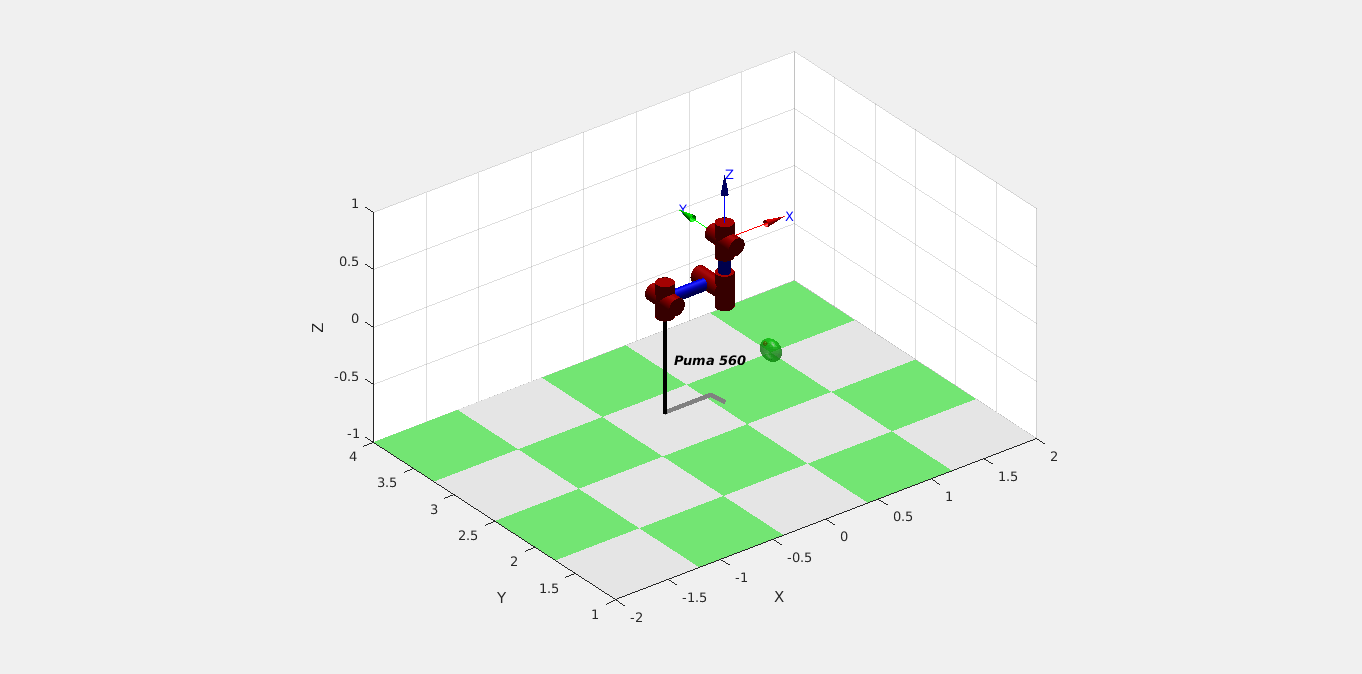

frameCX = -1.7257e-06

frameCY = 1.6829

frameCZ = 0.1596

RTx = 0.0685

RTy = 0.1075

RTz = 0.0883

teX =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0107   -0.0102   -0.0087   -0.0063   -0.0033   -0.0000    0.0033    0.0063    0.0087    0.0102    0.0107    0.0102    0.0087    0.0063    0.0033   -0.0000   -0.0033   -0.0063   -0.0087   -0.0102   -0.0107
   -0.0212   -0.0201   -0.0171   -0.0124   -0.0065   -0.0000    0.0065    0.0124    0.0171    0.0201    0.0212    0.0201    0.0171    0.0124    0.0065   -0.0000   -0.0065   -0.0124   -0.0171   -0.0201   -0.0212
   -0.0311   -0.0296   -0.0252   -0.0183   -0.0096   -0.0000    0.0096    0.0183    0.0251    0.0296    0.0311    0.0296    0.0251    0.0183    0.0096   -0.0000   -0.0096   -0.0183   -0.0252   -0.0296   -0.0311
   -0.0403   -0.0383   -0.0326   -0.0237   -0.0124   -0.0000    0.0124    0.0237    0.0326    0.0383    0.0402    0.0383    0.0326    0.0237    0.0124

teY =     1.6829    1.6829    1.6829    1.6829    1.6829    1.6829    1.6829    1.6829    1.6829    1.6829    1.6829    1.6829    1.6829    1.6829    1.6829    1.6829    1.6829    1.6829    1.6829    1.6829    1.6829
    1.6829    1.6777    1.6730    1.6693    1.6669    1.6661    1.6669    1.6693    1.6730    1.6777    1.6829    1.6881    1.6928    1.6965    1.6989    1.6997    1.6989    1.6965    1.6928    1.6881    1.6829
    1.6829    1.6726    1.6634    1.6560    1.6513    1.6497    1.6513    1.6560    1.6634    1.6726    1.6829    1.6932    1.7024    1.7098    1.7145    1.7161    1.7145    1.7098    1.7024    1.6932    1.6829
    1.6829    1.6678    1.6542    1.6434    1.6365    1.6341    1.6365    1.6434    1.6542    1.6678    1.6829    1.6980    1.7116    1.7224    1.7293    1.7317    1.7293    1.7224    1.7116    1.6980    1.6829
    1.6829    1.6634    1.6458    1.6318    1.6228    1.6197    1.6228    1.6318    1.6458    1.6634    1.6829    1.7024    1.7200    1.7340    1.7430

teZ =     0.0713    0.0713    0.0713    0.0713    0.0713    0.0713    0.0713    0.0713    0.0713    0.0713    0.0713    0.0713    0.0713    0.0713    0.0713    0.0713    0.0713    0.0713    0.0713    0.0713    0.0713
    0.0724    0.0724    0.0724    0.0724    0.0724    0.0724    0.0724    0.0724    0.0724    0.0724    0.0724    0.0724    0.0724    0.0724    0.0724    0.0724    0.0724    0.0724    0.0724    0.0724    0.0724
    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756
    0.0809    0.0809    0.0809    0.0809    0.0809    0.0809    0.0809    0.0809    0.0809    0.0809    0.0809    0.0809    0.0809    0.0809    0.0809    0.0809    0.0809    0.0809    0.0809    0.0809    0.0809
    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882

plotEllipsoidFromFrame(VS,'g');


% patch(circle2(1,:), circle2(2,:), circle2(3,:),'r');



% 
% tumor_P = [tumorh/2 0.5 0.5]
% 
% start_P = transl(tumor_P)
% [tumorZoneX, tumorZoneY, tumorZoneZ] = ellipsoid(tumor_P(1),tumor_P(2),tumor_P(3),tumorw/2,tumord/2,tumorh/2);
% patchedTumor = surf2patch(tumorZoneX,tumorZoneY,tumorZoneZ);
% figure(2)
% %% tumor_EE = p560.ikine6s(start_P*troty(90,'deg')*trotx(90,'deg')*troty(90,'deg')*trotx(-45,'deg'));
% 
% hold on
% patch(patchedTumor);



10.- Prepare a script that perform trepanation.

*Add your comemnts her**e.....be concise*

%% put your code Here 
mdl_puma560
figure(8)
robotY = mainTableH/2 + skullh/2 + 0.5;
robotPosition = mainTablePosition + [0 robotY 0];
p560.base = transl(robotPosition);
p560.plot(qz, 'workspace',[-2 2 1 4 -1 1],'tilesize',1);
hold on;
plotEllipsoidFromFrame(VT,'r');
plotEllipsoidFromFrame(VS,'g');

11.- Prepare a script that perform tumor burning with the laser.

*Add your comemnts her**e.....be concise*

%% put your code Here
mdl_puma560
figure(8)
robotY = mainTableH/2 + skullh/2 + 0.5;
robotPosition = mainTablePosition + [0 robotY 0];
p560.base = transl(robotPosition);
p560.plot(qz, 'workspace',[-2 2 1 4 -1 1],'tilesize',1);
hold on;
plotEllipsoidFromFrame(VT,'r');
plotEllipsoidFromFrame(VS,'g');

*Second approach:**  Assume that the ZX plane of the Robot is not aligned with plane of symetry of the human body and it is needed a orientation calibration.*

12.-Get the transformation that maps tumor points in Robot Frame. See teacher help: Triangle.mlx

*Add your comemnts her**e.....be concise*

%% put your code Here 
mdl_puma560
figure(9)
robotY = mainTableH/2 + skullh/2 + 0.5;
robotPosition = mainTablePosition + [0 robotY 0];
p560.base = transl(robotPosition);
p560.plot(qz, 'workspace',[-2 2 1 4 -1 1],'tilesize',1);
hold on;
plotEllipsoidFromFrame(VT,'r');
plotEllipsoidFromFrame(VS,'g');

13.- Print the tumor points in Robot Frame.

*Add your comemnts her**e.....be concise*

%% put your code Here 
mdl_puma560
figure(10)
robotY = mainTableH/2 + skullh/2 + 0.5;
robotPosition = mainTablePosition + [0 robotY 0];
p560.base = transl(robotPosition);
p560.plot(qz, 'workspace',[-2 2 1 4 -1 1],'tilesize',1);
hold on;
plotEllipsoidFromFrame(VT,'r');
plotEllipsoidFromFrame(VS,'g');

14.-Use the script that perform a biopsy. Zoom in the scene

*Add your comemnts her**e.....be concise*

%% put your code Here 
mdl_puma560
figure(11)
robotY = mainTableH/2 + skullh/2 + 0.5;
robotPosition = mainTablePosition + [0 robotY 0];
p560.base = transl(robotPosition);
p560.plot(qz, 'workspace',[-2 2 1 4 -1 1],'tilesize',1);
hold on;
plotEllipsoidFromFrame(VT,'r');
plotEllipsoidFromFrame(VS,'g');

15.- Use the  script that perform trepanation.

*Add your comemnts her**e.....be concise*

%% put your code Here 
mdl_puma560
figure(12)
robotY = mainTableH/2 + skullh/2 + 0.5;
robotPosition = mainTablePosition + [0 robotY 0];
p560.base = transl(robotPosition);
p560.plot(qz, 'workspace',[-2 2 1 4 -1 1],'tilesize',1);
hold on;
plotEllipsoidFromFrame(VT,'r');
plotEllipsoidFromFrame(VS,'g');

16.- Use the script that perform tumor burning with the laser.

*Add your comemnts her**e.....be concise*

%% put your code Here  
mdl_puma560
figure(13)
robotY = mainTableH/2 + skullh/2 + 0.5;
robotPosition = mainTablePosition + [0 robotY 0];
p560.base = transl(robotPosition);
p560.plot(qz, 'workspace',[-2 2 1 4 -1 1],'tilesize',1);
hold on;
plotEllipsoidFromFrame(VT,'r');
plotEllipsoidFromFrame(VS,'g');

## Auxiliar Functions

Funcions auxiliars

function drawTable(tablePointsMatrix,tableColor)
tablePolygonX = tablePointsMatrix(1,:);
tablePolygonY = tablePointsMatrix(2,:);
tablePolygonZ = tablePointsMatrix(3,:);
fill3(tablePolygonX,tablePolygonY,tablePolygonZ,tableColor);
alpha 0.3;
end
function tablePoints = getTablePointsMatrixFromCentre(centrePoint,tableWidth,tableHeigth,tilingOffset)
dx = tableWidth/2;
dy = tableHeigth/2;
dz = tilingOffset;
centrePointsAs4x3Matrix = repmat(centrePoint ,4,1);
tablePointsAs4x3Matrix = [-dx -dy 0;dx -dy 0; dx dy dz; -dx dy dz];
tablePointsFromCentre = centrePointsAs4x3Matrix + tablePointsAs4x3Matrix;
tablePoints = tablePointsFromCentre';
end
function plotEllipsoidFromFrame(myFrame,color)
frameCX = (max(myFrame(:,1)) + min(myFrame(:,1)))/2
frameCY = (max(myFrame(:,2)) + min(myFrame(:,2)))/2
frameCZ = (max(myFrame(:,3)) + min(myFrame(:,3)))/2
RTx = (max(myFrame(:,1)) - min(myFrame(:,1)))/2
RTy = (max(myFrame(:,2)) - min(myFrame(:,2)))/2
RTz = (max(myFrame(:,3)) - min(myFrame(:,3)))/2
% circle2 = circle(tumorPosition, tumorw);
[teX, teY, teZ] = ellipsoid(frameCX,frameCY,frameCZ,RTx,RTy,RTz)
tumorellipsoidPatch = surf2patch(teX, teY, teZ);
patch(tumorellipsoidPatch,'FaceAlpha',0.5,'LineStyle','none','FaceColor',color);
end

    
    